# Step-by-Step Tutorial for SAND Alignment

Appendix A

This appendix provides a step-by-step tutorial for aligning SAND-processed NMR peak tables using the expanding-window alignment approach and pH-guided iterative tracing (pHIT). The purpose of this tutorial is to provide detail for the workflow described in Chapter 2. The tutorial uses the Known Mixture dataset provided in the[ GitHub repository](https://github.com/DeannaLanier/DL_SAND_Alignment.git).

**This workflow includes the following major stages:**

- Add required MATLAB paths and toolboxes

- Load SAND peak tables

- Reconstruct frequency-domain spectra from SAND peak tables

- Process peak tables prior to alignment

- Apply pHIT alignment 

- Apply expanding-window alignment

- Visually inspect alignment results

**Required files for this tutorial:**

- SAND peak table CSV files

- MATLAB functions from the GitHub

- Edison Lab metabolomics toolbox

## Setting up

- **Download the or clone the repository:** [https://github.com/DeannaLanier/DL_SAND_Alignment.git](https://github.com/DeannaLanier/DL_SAND_Alignment.git)

- **Choose your MATLAB environment:** Place the repository on either NMRbox or your local machine.

- **Open the tutorial file:** Launch MATLAB and open the **SANDAlignment_Tutorial.mlx** script, located in the "workflows" folder.

## Step 1: Add Paths to project

This step adds the required MATLAB functions and example data folder to the active MATLAB path. The Edison Lab metabolomics toolbox contains functions used for NMR metabolomics processing and visualization. The SAND alignment toolbox contains the workflow-specific functions used in this tutorial. Users should update the folder paths below to match the location of these repositories on their local computer or NMRbox environment.

Required toolboxes: [Edison lab metabolomics toolbox](https://github.com/edisonomics/metabolomics_toolbox.git), [SAND alignment functions](https://github.com/DeannaLanier/DL_SAND_Alignment.git)

**NMRbox users: **If using NMRbox, run the following command to activate the Edison Lab metabolomics toolbox:

activate_metabolomics_toolbox

**Local machine users:** If running the workflow locally, download the[ Edison Lab toolbox ](https://github.com/edisonomics/metabolomics_toolbox.git)(in addition to the SAND alignment) and update the paths below

Add the path to the alignment toolbox to the second line below.

**Add toolboxes to path**

% Update these paths to match the location of the toolboxes on your computer
edisonToolboxPath = '/path/to/Edison_lab_UGA';

paths = struct with fields:
    Data: '/Users/deannalanier/Desktop/GitHub/DL_SAND_Alignment/Data/Known_Mixture_Dataset'


alignmentToolboxPath = '/path/to/DL_SAND_Alignment';

addpath(genpath(edisonToolboxPath))
addpath(genpath(alignmentToolboxPath))


**Add project directory to path**

% Update this path to the folder containing the example SAND peak tables
paths.Data = '/path/to/DL_SAND_Alignment/Data/Known_Mixture_Dataset';


After this step, MATLAB should be able to locate the required functions used throughout the tutorial. The variable `paths.Data` should point to the folder containing the example SAND peak tables.

## Step 2: Load the SAND peak tables

**Load SAND CSVs **

This step imports the SAND-processed peak tables into the workspace. Each sample is saved as an individual peak table containing the peak frequency, amplitude, and decay.

**Inputs: **path to the folder containing your SAND peak table CSVs

%Load peak tables

[~, originalData.SandTable, originalData.array_original] = loadSandPeaksTables(paths.Data);


**Outputs: **

After loading the data, your should have the variable  **originalData** which will contain your SAND tables. 

Each row in **originalData.SandTable** corresponds to one sample. the "**Peaks**" column contains the SAND peak tables associated with that sample.

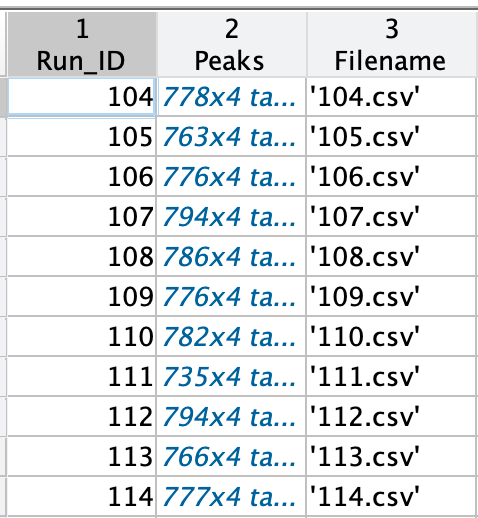

The** "Peaks"** column contains the individual SAND peak table for each sample. 

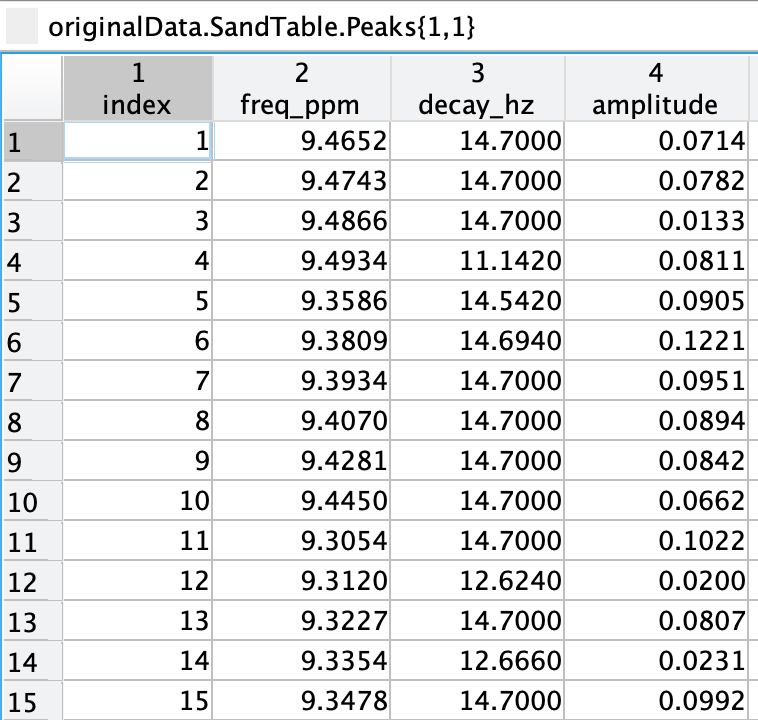

### Step 2.2 :Frequency Reconstruction

SAND peak tables can be reconstructed into frequency-domain spectra for visualization. This step converts the parameterized peak tables into a spectral matrix (`X`) and corresponding ppm axis for plotting and downstream inspection.

**Inputs: **Sand table or array.

**Optional Parameters based on the dataset:**

**Expected Outputs: **

reconstructed ppm and X matrix to be used for plotting

% Reconstruct frequency-domain spectra from SAND peak tables
[originalData.reconstructedPPMs, originalData.reconstructed_ppm, originalData.X] = reconstructSpectraFromPeaks(originalData.array_original);


**plot**

The reconstructed spectra can now be visualized to confirm that the SAND peak tables were imported and reconstructed correctly.

**Expected Result:**

The reconstructed spectra should resemble a conventional 1D NMR spectrum

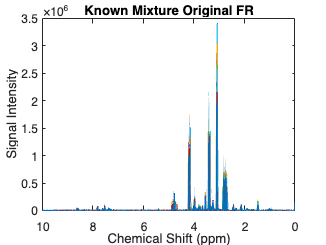

set(0,'DefaultFigureVisible','off')

figure
plot(originalData.reconstructed_ppm, originalData.X', ...
    'LineWidth', 1.5)

set(gca,'XDir','reverse')
xlabel('Chemical Shift (ppm)','FontSize',12)
ylabel('Signal Intensity','FontSize',12)
title('Known Mixture Original FR','FontSize',14)

xlim([0 10])   % zoom to 0–10 ppm
set(gca,'FontSize',12)
%whichLine();

## Step 3: Processing

3.1 - Condense underlying peaks (required to align and analyze). 

3.2 - Region removal (not required, but helpful to exclude solvent regions)

3.n - Any additional processing 

### 3.1 - Consolidate underlying peaks and recalculate the Decay

SAND models time-domain signals using exponential decay functions. As a result, SAND may generate multiple underlying simulated peaks to model a single observable resonance in the frequency domain. While retention of these underlying peaks is useful during signal detection and decomposition, it complicates downstream alignment and comparison across samples.To simplify downstream processing, underlying SAND peaks associated with the same observable resonance are consolidated into a single representative peak. Consolidation is performed using the reconstructed frequency-domain (FR) spectra by grouping all peaks located between two neighboring spectral minima. The resulting consolidated peak tables reduce redundancy and produce one representative row per observable resonance.

**Variables to set:**

- X matrix and ppms

- Operating frequency 

- sweep width

- Acquired time points in the FID

**Expected Outputs: **

ConReconstructionarray: Reconstructed spectra generated after consolidation

ConReconstructionpeakTables: Consolidated SAND peak tables

% Define inputs required for peak consolidation
FR.XN = originalData.X; %X matrix
FR.ppm = originalData.reconstructedPPMs; % PPMs
FR.ppm1 =originalData.reconstructed_ppm %ppms


nmrParams.B0 = 600.13282159; %Operating Frequency
nmrParams.SW = 12019.2307692308; %sweep width
nmrParams.TD = 65536; % acquired time points in the FID


[originalData.ConReconstructionarray, originalData.ConReconstructionpeakTables] = sandReconstruction(originalData.array_original, FR, nmrParams);

**Create a new variable "SandTable" in your workspace. **To preserve the original SAND peak tables, the consolidated peaks are added as a new column within the existing `SandTable` structure rather than overwriting the original `Peaks` column.

%% Add consolidated peak tables to SandTable
% Add consolidated peak tables as a new column named 'Con'

SandTable = [originalData.SandTable(:, 1:2), table(originalData.ConReconstructionpeakTables(:), 'VariableNames', {'Con'}), originalData.SandTable(:, 3:end)];

% Add new Peak table to the original table (or struct)

**Expected SandTable: **The consolidated peak tables should contain fewer rows than the original SAND peak tables because multiple underlying modeled peaks corresponding to a single observable resonance have been grouped into one representative peak entry.

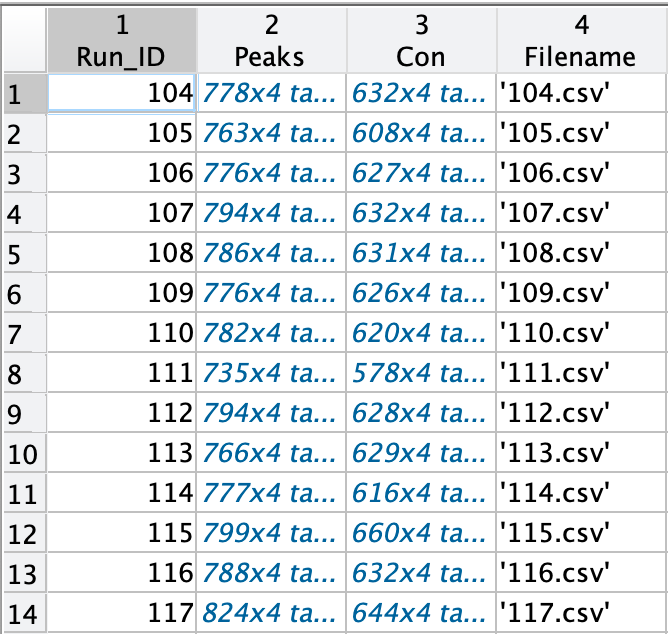

### 3.2 Region Removal

This step removes spectral regions that are not needed for downstream alignment or analysis (like solvents). Regions should be removed when they contain peaks that are not biologically or analytically relevant to the alignment task. For urine datasets, this may include urea or residual water regions. For serum datasets, this may include methanol or other solvent-associated regions.

**Define regions to remove**

% regions defines the ppm boundaries to remove.

regions = [ 4.6   5.0; -0.5  -0.006];  
 
[SandTable, processing] = removePeakRegionsFromSandTable(SandTable, regions);

**This function also saves metadata at each step. This includes: **

- Removed peaks tables

- Retained peaks tables

- ppm regoins removed

- per-sample peak counds before and after filtering

%% Optional: inspect per-sample region removal summary

%processing.metadata.info.RR.perSample  

**Reconstruct the retained and removed peak tables for visual inspection.**

Verify that the intended regions were removed and that the remaining spectra retain the expected biological signal.

**Remove regions expected outputs:**

   [processing.RR_removed.reconstructedPPMs, processing.RR_removed.reconstructed_ppm, processing.RR_removed.X] = reconstructSpectraFromPeaks(processing.metadata.table.Regions_Removed);
   [processing.RR_kept.reconstructedPPMs, processing.RR_kept.reconstructed_ppm, processing.RR_kept.X] = reconstructSpectraFromPeaks(SandTable, 'peaksColumn','Con_RR');

**Plot**

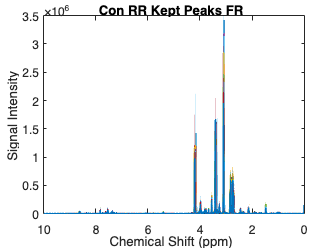

   %Plot the retained peaks

   set(0,'DefaultFigureVisible','off')
   figure;

   plot(processing.RR_kept.reconstructed_ppm, processing.RR_kept.X, 'LineWidth', 1.5);
   set(gca, 'XDir', 'reverse');
   xlabel('Chemical Shift (ppm)', 'FontSize', 12);
   ylabel('Signal Intensity', 'FontSize', 12);
   title('Con RR Kept Peaks FR', 'FontSize', 14);
   xlim([0 10])   % zoom to 0–10 ppm
   %legend('show');
   set(gca, 'FontSize', 12);

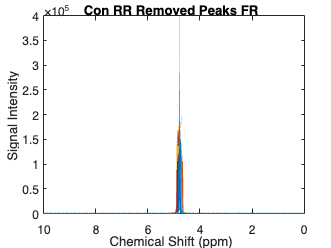



   %Plot the removed peaks
   set(0,'DefaultFigureVisible','off')
   figure;

   plot(processing.RR_removed.reconstructed_ppm, processing.RR_removed.X, 'LineWidth', 1.5);

   set(gca, 'XDir', 'reverse');
   xlabel('Chemical Shift (ppm)', 'FontSize', 12);
   ylabel('Signal Intensity', 'FontSize', 12);
   title('Con RR Removed Peaks FR', 'FontSize', 14);
   xlim([0 10])   % zoom to 0–10 ppm
   %legend('show');
   set(gca, 'FontSize', 12);

   whichLine();

### **3.3 Apply Amplitude threshold**

This step removes low-amplitude peaks that are unlikely to contribute meaningfully to downstream alignment. Filtering low-amplitude peaks reduces noise, decreases the number of peaks that must be aligned, and improves the interpretability of the resulting peak tables. The amplitude threshold defines the minimum peak amplitude retained in the processed peak table. Peaks with amplitudes below the threshold are removed.

There are two options for applying threshold:

- Automatic: If no amplitude threshold is manually specified, then for each sample, the max amplitude below 0ppm will be used as the threshold.

- Manual selection: a set value can be selected as the threshold using the parameter 'AmpThresh'.

% how to call automatic threshold: 
% [SandTable, processing] = ampFilter_DL(SandTable, 'Processing', processing);

% Apply amplitude threshold


[SandTable, processing] = ampFilter_DL(SandTable,'AmpThresh',0.05, 'Processing', processing);  

Created Con_RR_AF using PER-SAMPLE amplitude thresholds (Input=Con_RR).


**This function also saves metadata at each step. This includes: **

- Removed peaks tables

- Retained peaks tables

- per-sample eak counds before and after filtering

% Optional: inspect per-sample amplitude filtering summary

 %processing.metadata_AT.info.AT.perSample


**Reconstruct the retained and removed peak tables**

Verify that the intended peaks were removed and that the remaining spectra retain the expected biological signal.

**Remove regions expected outputs:**

 [processing.AF_removed.reconstructedPPMs, processing.AF_removed.reconstructed_ppm, processing.AF_removed.X] = reconstructSpectraFromPeaks(processing.metadata_AT.table.Amplitude_Removed);
 [processing.AF_kept.reconstructedPPMs, processing.AF_kept.reconstructed_ppm, processing.AF_kept.X] = reconstructSpectraFromPeaks(SandTable, 'peaksColumn','Con_RR_AF');

**Plot **

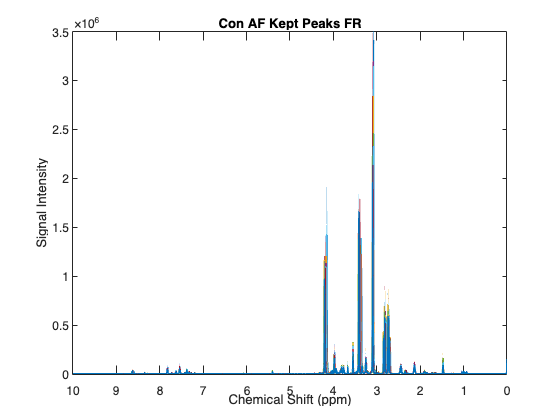

 set(0,'DefaultFigureVisible','off')
 figure;

 plot(processing.AF_kept.reconstructed_ppm, processing.AF_kept.X, 'LineWidth', 1.5);

 set(gca, 'XDir', 'reverse');
 xlabel('Chemical Shift (ppm)', 'FontSize', 12);
 ylabel('Signal Intensity', 'FontSize', 12);
 title('Con AF Kept Peaks FR', 'FontSize', 14);
 xlim([0 10])   % zoom to 0–10 ppm
 %legend('show');
 set(gca, 'FontSize', 12);

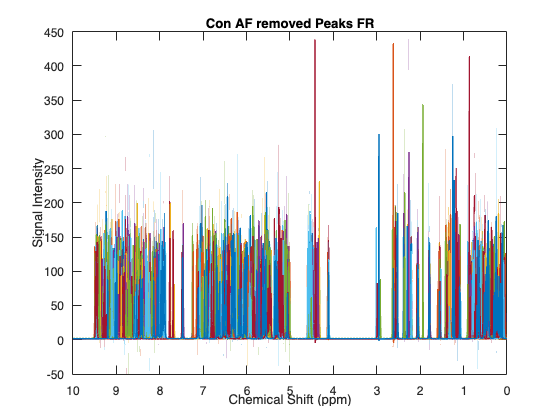



 set(0,'DefaultFigureVisible','off')
 figure;
 plot(processing.AF_removed.reconstructed_ppm, processing.AF_removed.X, 'LineWidth', 1.5);

 set(gca, 'XDir', 'reverse');
 xlabel('Chemical Shift (ppm)', 'FontSize', 12);
 ylabel('Signal Intensity', 'FontSize', 12);
 title('Con AF removed Peaks FR', 'FontSize', 14);
 xlim([0 10])   % zoom to 0–10 ppm
 %legend('show');
 set(gca, 'FontSize', 12);

 whichLine();

### Step 3.4 Separate near-overlapping peaks

Peaks located within a very small ppm tolerance of another peak were separated from the main peak table prior to automated alignment. These peaks were not discarded from the dataset fully, only removed at this stage to be reintegrated. This step is included because near overlapping peaks can cause the expanding window apprach to group unrelated peaks, or "end" due to what would be considered overcrowding.These peaks can also interfere with pHIT curve tracing.

when two peaks occur within the specified ppm tolerance, the higher-amplitude peak is retained in the main alignment table, while the lower-amplitude overlapping peak is saved separately.

%Separate overlapping peaks 

SandTable = filterOverlappingPeaksInSandTable( ...
    SandTable, ...
    'PeakTableField', 'Con_RR_AF', ...
    'NewPeakTableField', 'Con_RR_AF2', ...
    'RemovedPeakTableField', 'Con_RR_AF2_Removed', ...
    'PPMTolerance', 0.003, ...
    'Verbose', true);

**Reconstruct **

% Reconstruct retained 

[processing.Con_RR_AF2.reconstructedPPMs, ...
 processing.Con_RR_AF2.reconstructed_ppm, ...
 processing.Con_RR_AF2.X] = reconstructSpectraFromPeaks( ...
    SandTable, ...
    'ppmColName', 'freq_ppm', ...
    'peaksColumn', 'Con_RR_AF2');
%and flagged overlapping peaks

[processing.Con_RR_AF2_Removed.reconstructedPPMs, ...
 processing.Con_RR_AF2_Removed.reconstructed_ppm, ...
 processing.Con_RR_AF2_Removed.X] = reconstructSpectraFromPeaks( ...
    SandTable, ...
    'ppmColName', 'freq_ppm', ...
    'peaksColumn', 'Con_RR_AF2_Removed');

**Expected result:**

`Con_RR_AF2` contains the retained peak table used for automated alignment while `Con_RR_AF2_Removed` contains peaks flagged as overlapping

**Plot **

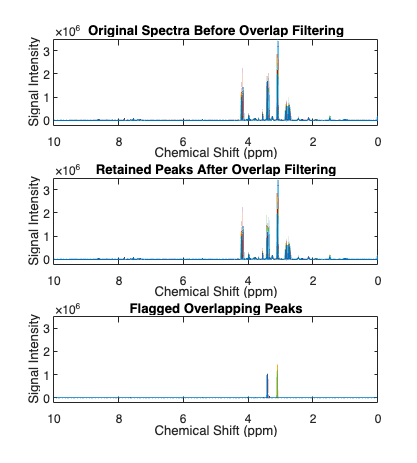

%% Compare spectra before and after overlap filtering
set(0,'DefaultFigureVisible','off')

figure('Position',[100 100 900 1000])

% Original AF-kept spectra

ax1 = subplot(3,1,1);

plot(processing.AF_kept.reconstructed_ppm, ...
    processing.AF_kept.X', ...
    'LineWidth',1.2)
set(gca,'XDir','reverse')
xlim([0 10])
xlabel('Chemical Shift (ppm)','FontSize',12)
ylabel('Signal Intensity','FontSize',12)
title('Original Spectra Before Overlap Filtering', ...
    'FontSize',14)
set(gca,'FontSize',12)

% Retained peaks

ax2 = subplot(3,1,2);

plot(processing.Con_RR_AF2.reconstructed_ppm, ...
    processing.Con_RR_AF2.X', ...
    'LineWidth',1.2)
set(gca,'XDir','reverse')
xlim([0 10])
xlabel('Chemical Shift (ppm)','FontSize',12)
ylabel('Signal Intensity','FontSize',12)
title('Retained Peaks After Overlap Filtering', ...
    'FontSize',14)
set(gca,'FontSize',12)

% Flagged overlapping peaks

ax3 = subplot(3,1,3);

plot(processing.Con_RR_AF2_Removed.reconstructed_ppm, ...
    processing.Con_RR_AF2_Removed.X', ...
    'LineWidth',1.2)
set(gca,'XDir','reverse')
xlim([0 10])
xlabel('Chemical Shift (ppm)','FontSize',12)
ylabel('Signal Intensity','FontSize',12)
title('Flagged Overlapping Peaks', ...
    'FontSize',14)
set(gca,'FontSize',12)

linkaxes([ax1 ax2 ax3],'xy')

## Step 4: Apply pHIT

### 4.1 Establish variables

% X matrix after processing
X = processing.Con_RR_AF2.X;

ppm = processing.Con_RR_AF2.reconstructed_ppm;

% Vertical spacing used for stacked plots
InterFactor=1000; 

**4.2 Select guide peak(s) and reorder**

The guide peak should be a well-resolved peak or multiplet that shifts consistently across samples. In this example, the selected guide region contains a doublet near 2.68–2.76 ppm. This guide peak is used to reorder samples according to their chemical shift behavior, allowing pH-responsive peaks to be visualized as smoother trajectories.

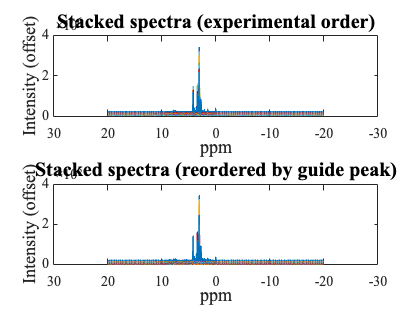

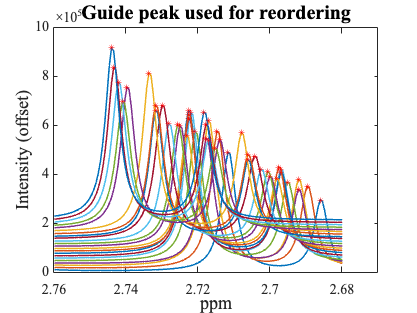

pHIT = struct with fields:
    out: [1×1 struct]


%% Select guide peak region

% Define ppm range containing the guide peak(s)

ppmRangeGuide = [2.68 2.76];  % right/left boundaries 
NP = 2;                         % number of guide peaks 


%Reorder the dataset based on the guide peak curve. 

pHIT.out = reorderSamplesByGuidePeak(ppm, X, ppmRangeGuide, NP, ...
    'InterFactor', 10000, ...
    'MakePlots', true)

### 4.3 Detect the ridges

The ridge detection step identifies groups of peaks that follow a consistent trajectory across the reordered samples. The steps below describe what the user should expect when running the function from the MATLAB Command Window.

**1 **This function first performs an automated global ridge detection across the reordered SAND peak table. After the initial detection, MATLAB displays a figure with two panels. The top panel shows the stacked, reordered frequency-reconstructed spectra. The bottom panel shows the corresponding SAND peak-table points in reordered sample space. Each colored vertical or curved trace represents a detected ridge candidate. 

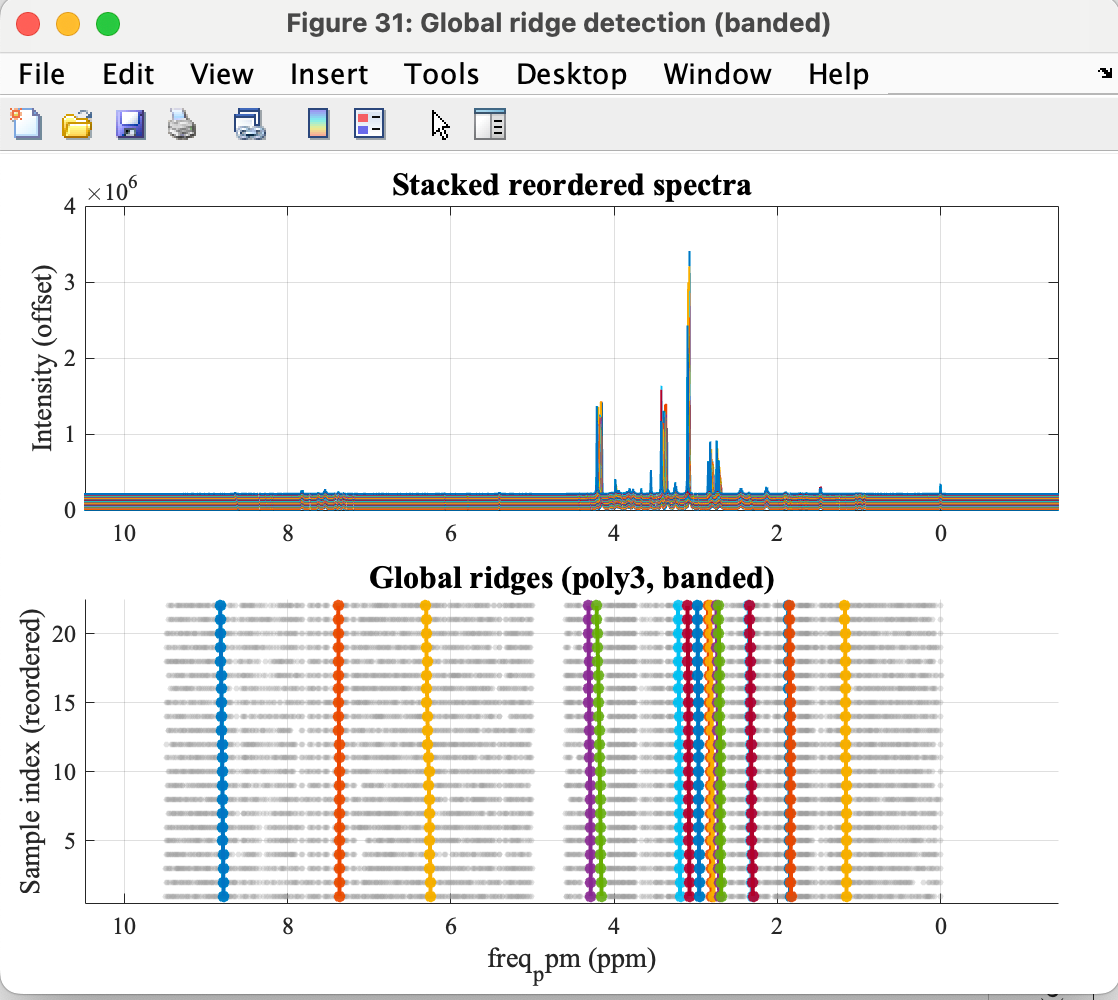

After reviewing the automatically detected ridges, press **Enter** in the Command Window to continue.

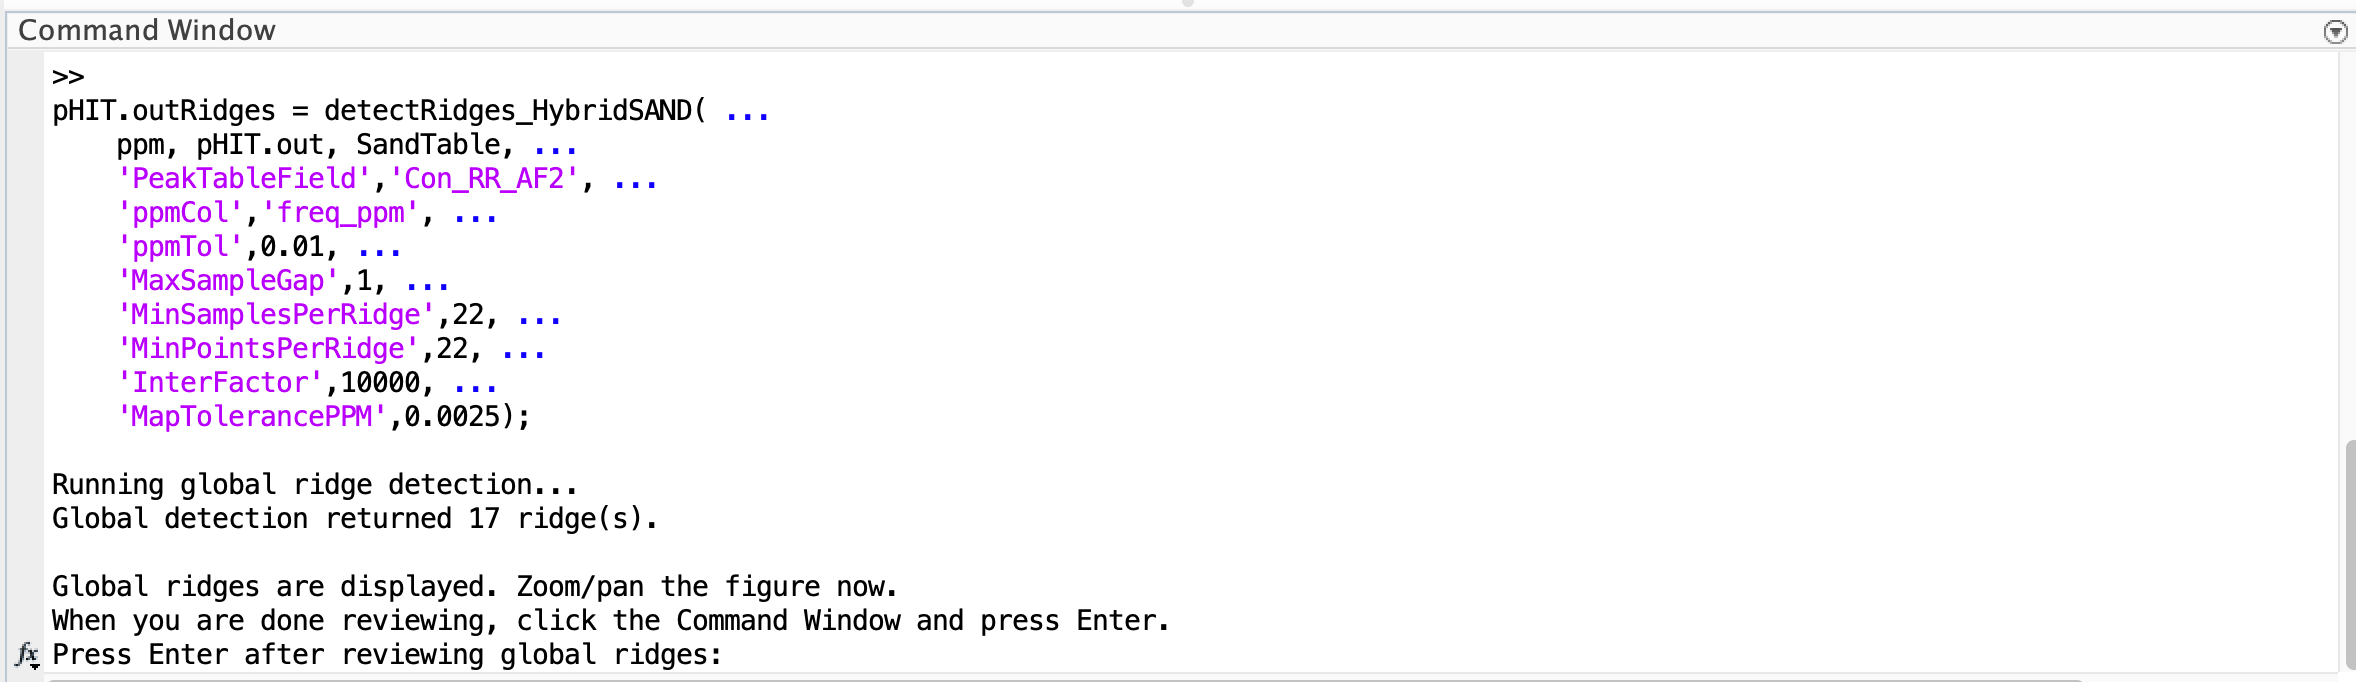

**2 ** A pop up window will open. If additional ridges are needed, select **Yes** when prompted to add ridges manually.

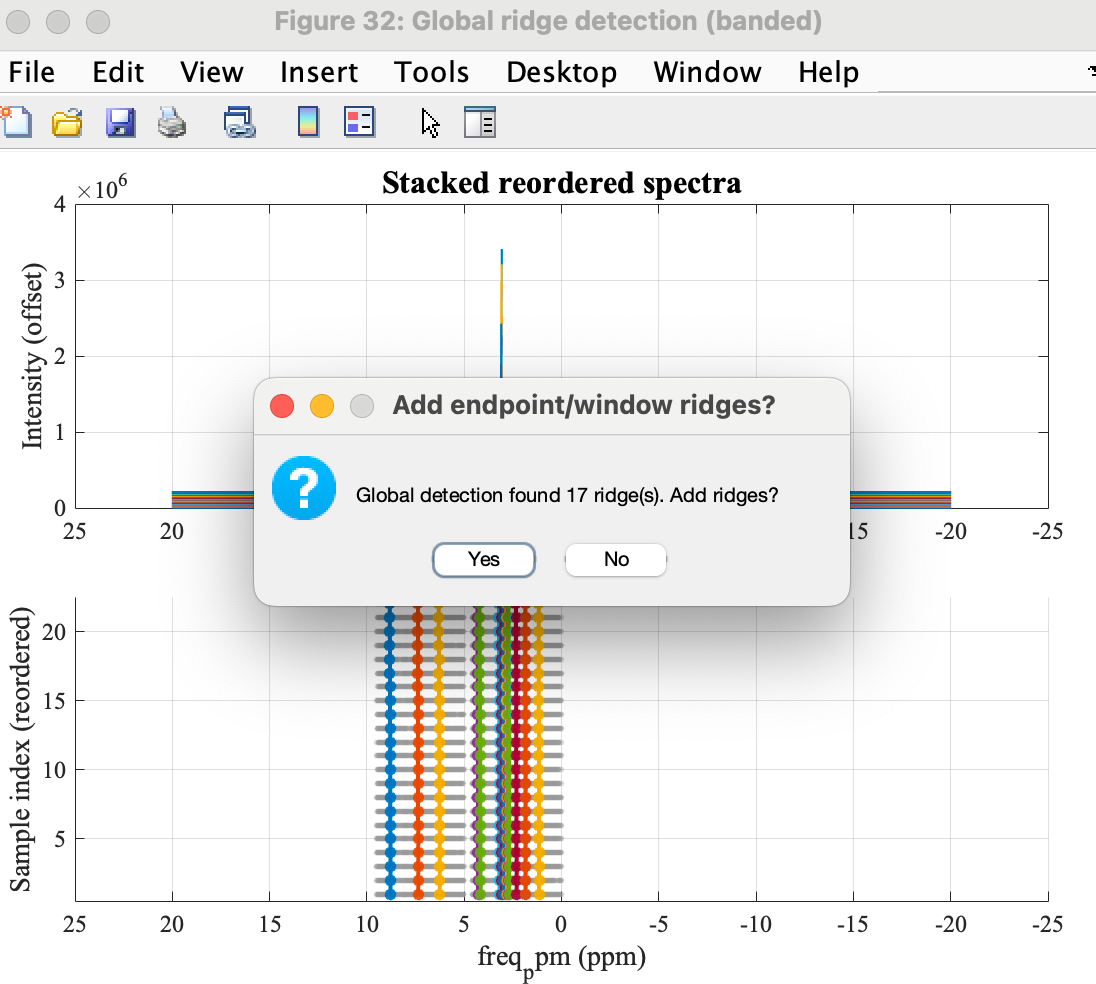

**3 **A new interactive figure will open. First, zoom into the spectral region of interest. Then select **Ready to click endpoints** in the top-right corner of the figure. Click one endpoint on each side of the ridge region to define the ppm window, then enter the expected number of peaks in that region. The function will attempt to trace the ridge within the selected window.

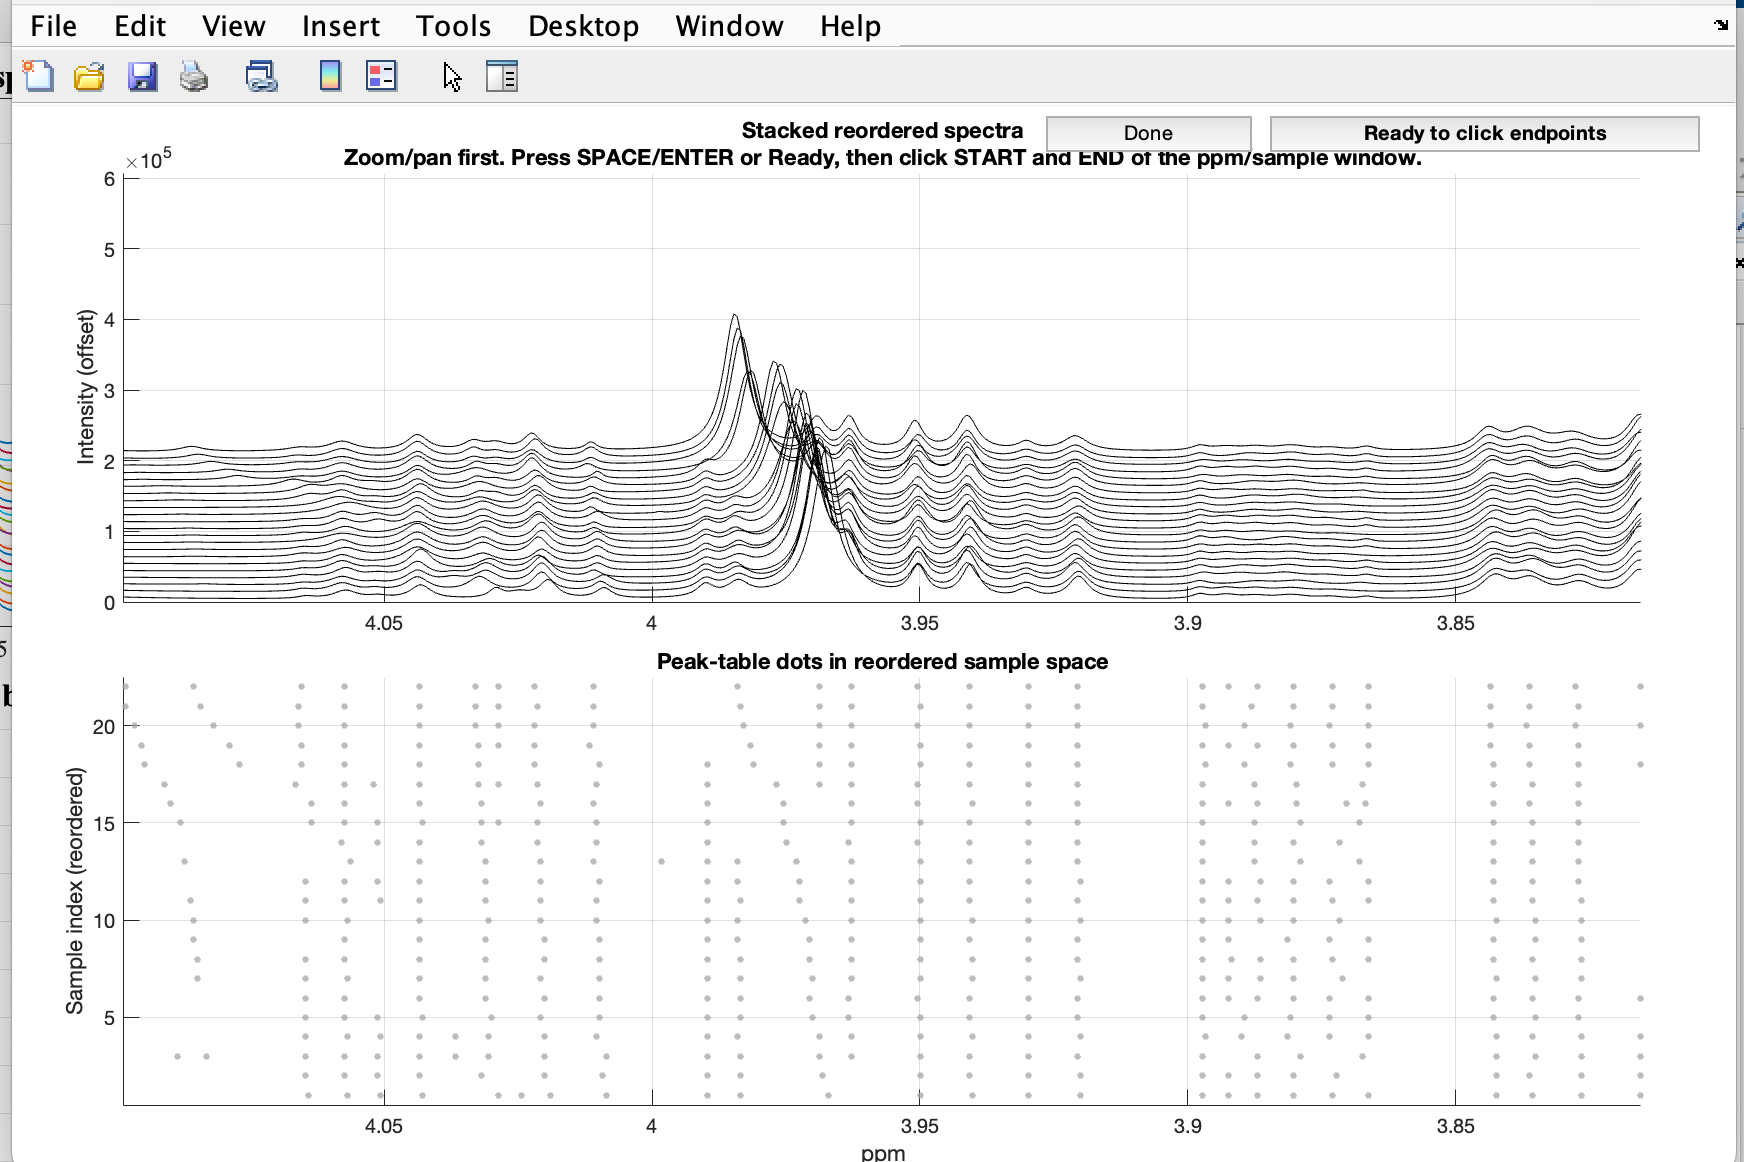

After the ridge is detected, inspect the proposed trace carefully. The function will display the detected ridge over the stacked spectra and the peak-table dot plot. Choose the option that best matches the quality of the detected ridge:

- **Accept + next**: keep the detected ridge and select another region. 

- **Reject + next**: discard the detected ridge and continue selecting regions. 

- **Accept + done**: keep the detected ridge and finish manual ridge selection.

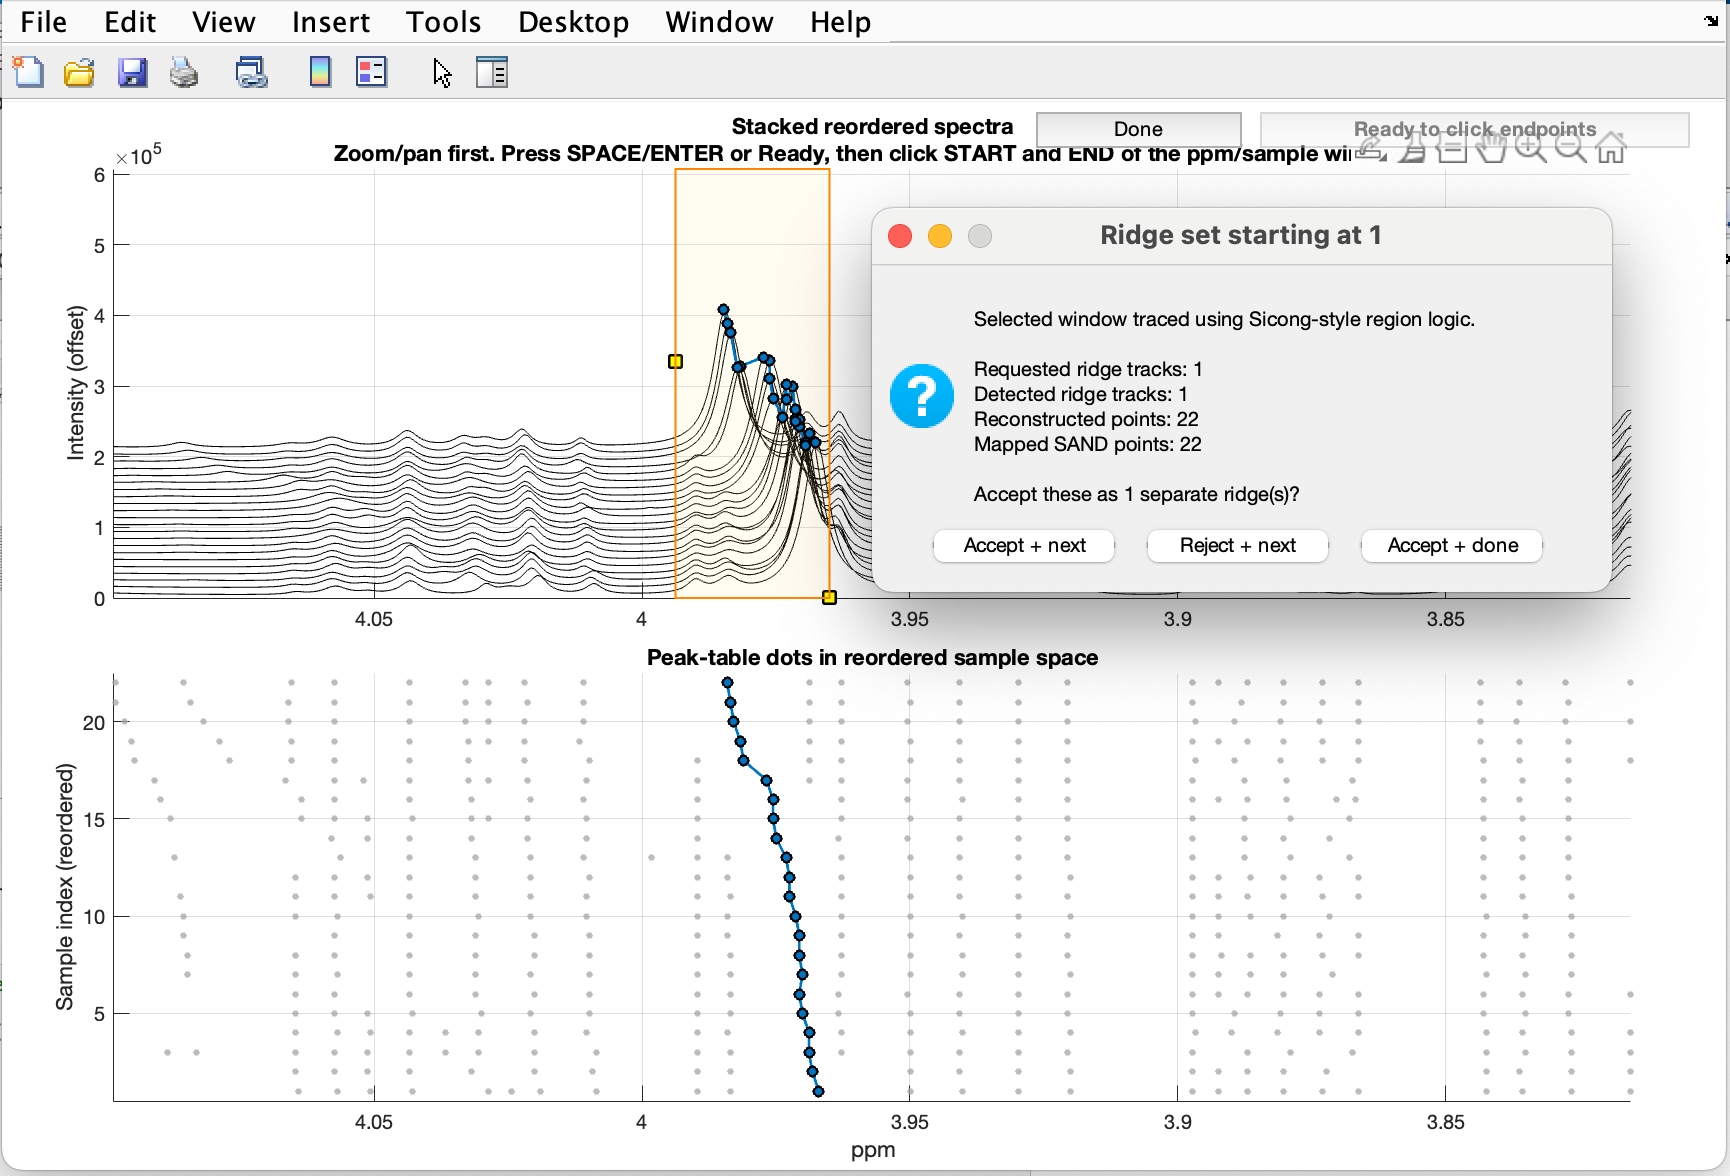

At the end of the process, the Command Window reports the number of automatically detected global ridges and the number of user-selected ridges. The final ridge output is stored in `pHIT.outRidges` and is used in later pHIT alignment steps.

Run the code block in the command window

% 4. Global ridge detection across all reordered peaks

pHIT.outRidges = detectRidges_HybridSAND( ...
    ppm, pHIT.out, SandTable, ...
    'PeakTableField','Con_RR_AF2', ...
    'ppmCol','freq_ppm', ...
    'ppmTol',0.01, ...
    'MaxSampleGap',1,...
    'MinPointsPerRidge',22, ...
    'InterFactor',10000, ...
    'MapTolerancePPM',0.0025);

### 4.4 Validate and plot Ridges

The ridge detection step may mis peaks within a ridge, or misclassify peaks as part of a ridge when it is not. To help ensure all ridges are correct, ridge validation is performed interactively prior to downstream pHIT alignment. The steps below describe the validation process and the expected user interactions.

When the validation function is run, instructions are displayed in the MATLAB Command Window describing the available validation options. The user can accept, reject, manually edit, or stop the validation process

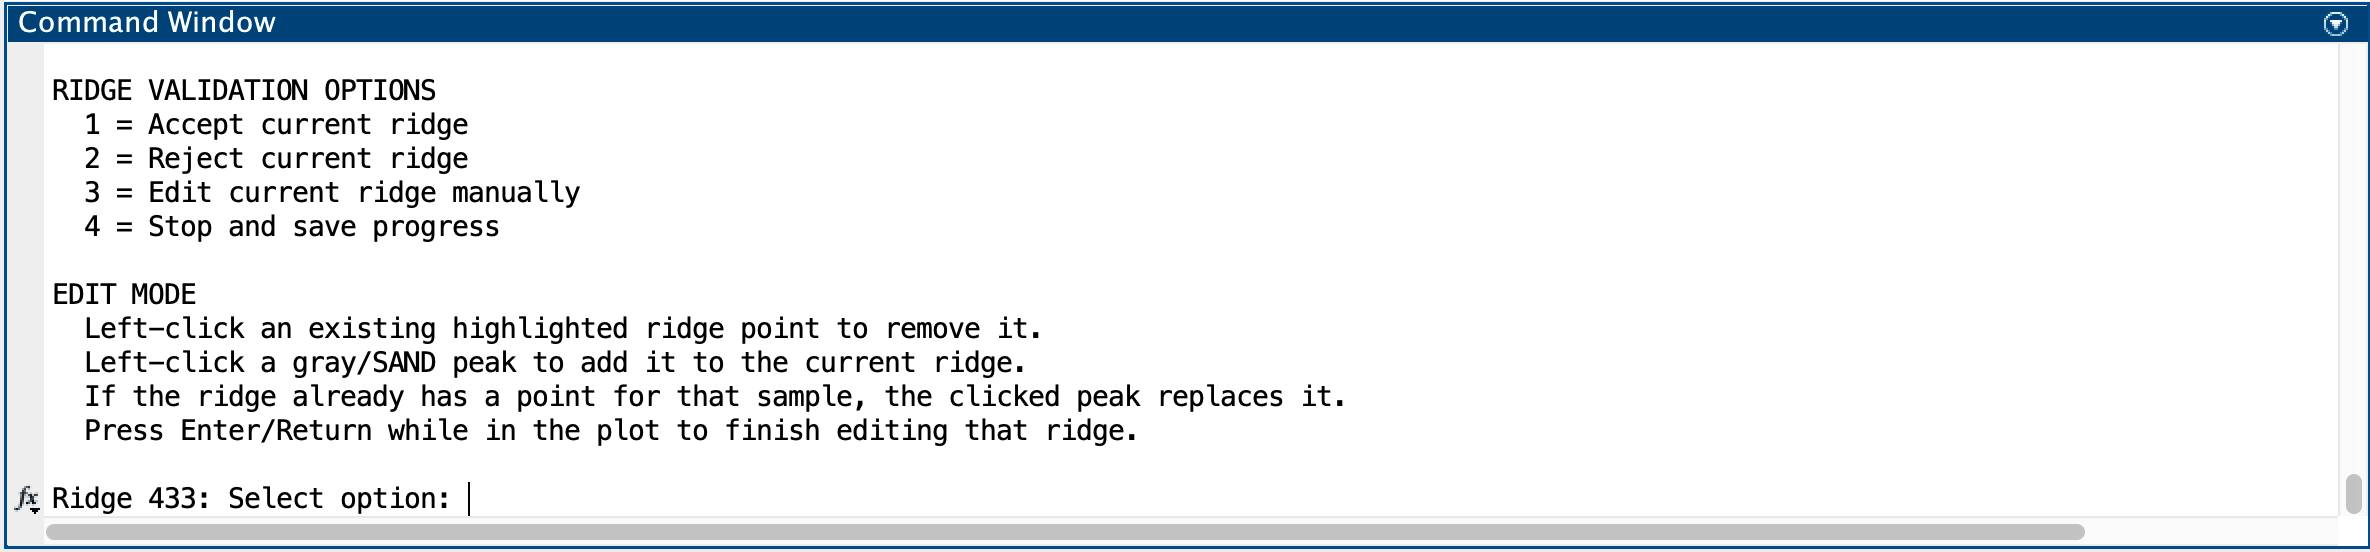 

The interactive validation window contains two panels:

- The top panel shows the stacked reordered frequency-reconstructed spectra. 

- The bottom panel shows the detected ridge overlaid on the reordered SAND peak-table points.

The highlighted ridge points represent the currently detected ridge trajectory being evaluated. The goal of validation is to confirm that the ridge follows the same observable shifting peak across all samples.

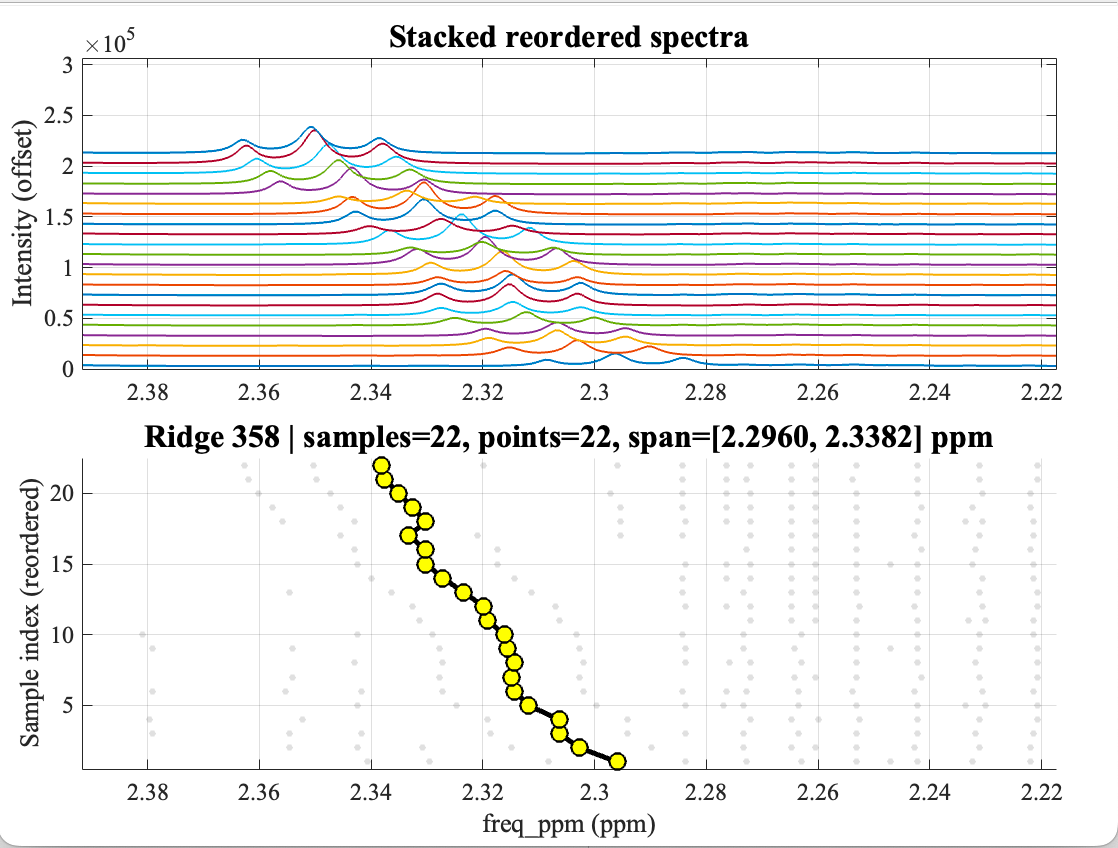

**Manual Ridge Editing**

If the detected ridge is incomplete or incorrectly mapped, enter **"**`3"` in the Command Window to activate manual editing.

During manual editing:

- Clicking a yellow highlighted ridge point removes that point from the ridge. 

- Clicking a gray SAND peak adds or replaces a ridge point. 

- If a ridge point already exists for that sample, the selected point replaces the existing ridge point. 

- Press **Enter** while the figure window is active to finish editing the current ridge. 

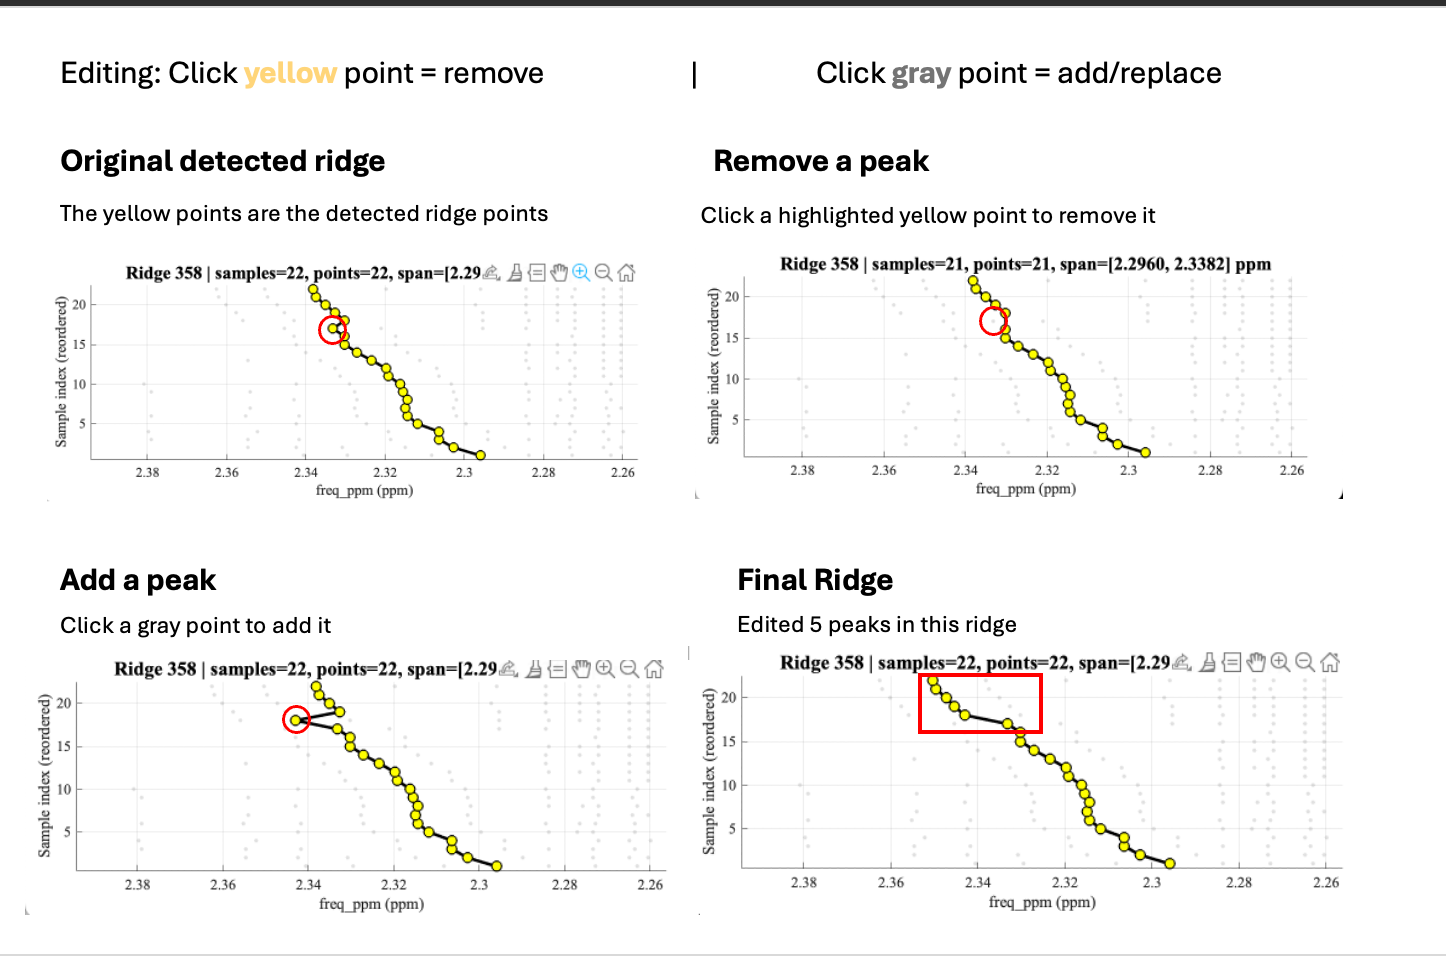

Updates are applied in real time and are reported in the MATLAB Command Window as points are added, removed, or replaced.

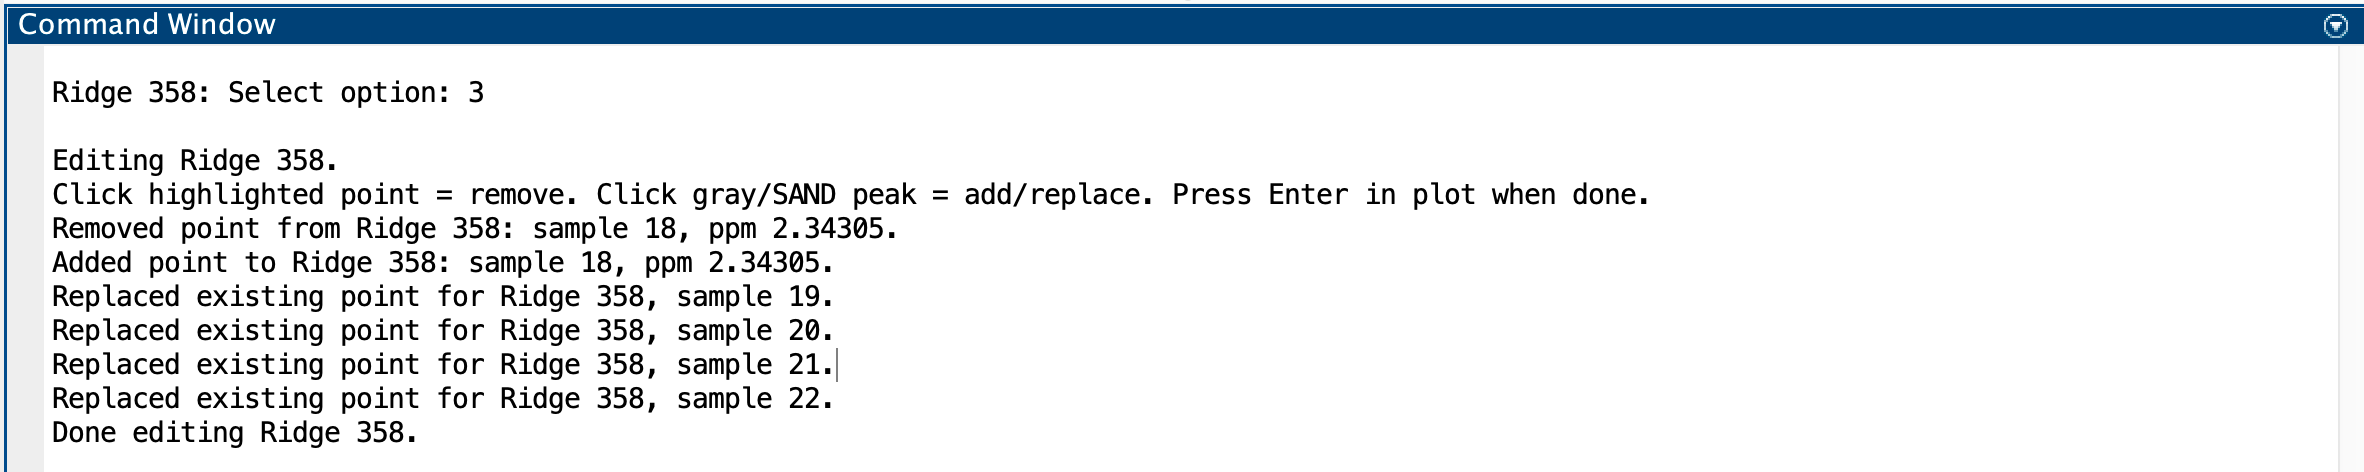

**During ridge validation, inspect whether:**

- ridge points incorrectly switch to neighboring peaks in crowded regions 

- missing points should be added manually 

Well-validated ridges should follow a biologically and spectrally consistent peak trajectory across the reordered dataset.

% Validate ridge trajectories interactively

pHIT.outVal = validateRidgesEditable( ...
    pHIT.outRidges, SandTable, ...
    'PeakTableField','Con_RR_AF2', ...
    'ppmCol','freq_ppm');

### 4.5 Final pHIT-Aligned Peak Tables

This step creates:

- aligned ridge-specific peak tables 

- reconstructed aligned spectra for visualization 

- updated SAND tables containing aligned and unaligned peaks separately 

Only peaks associated with validated ridge trajectories are modified during this step. Peaks not assigned to a validated ridge remain unchanged and are stored separately for downstream processing.

**1 Reconstruct and align ridges**

**parameters used:**

In this workflow, the median ppm position was used as the alignment statistic.

% Generate aligned peak tables from validated ridges

pHIT.outAligned = alignAndReconstructValidatedRidges( ...
    pHIT.outVal, SandTable, pHIT.out, ...
    'PeakTableField', 'Con_RR_AF2', ...
    'AlignStatistic', 'median', ...
    'NewFieldName', 'ValidatedAligned_Table');
    %% 

%reconstruct
[r_valid.reconstructedPPMs, r_valid.reconstructed_ppm, r_valid.X] = reconstructSpectraFromPeaks(pHIT.outAligned.alignedDataUpdated, 'peaksColumn','ValidatedAligned_Table', 'ppmColName', 'freq_ppm');
%% 

set(0,'DefaultFigureVisible','off')
 figure;
 plot(r_valid.reconstructed_ppm, r_valid.X, 'LineWidth', 1.5);

 set(gca, 'XDir', 'reverse');
 xlabel('Chemical Shift (ppm)', 'FontSize', 12);
 ylabel('Signal Intensity', 'FontSize', 12);
 title('pHit Aligned', 'FontSize', 14);
 xlim([0 10])   % zoom to 0–10 ppm
 %legend('show');
 set(gca, 'FontSize', 12);

 whichLine();

**2 Update the SAND table with aligned ridge information**

The validated pHIT ridge alignments are merged back into the main `SandTable` structure. This step separates:

- peaks associated with validated pHIT ridges 

- aligned ridge peaks 

- remaining non-pHIT peaks 

This separation preserves traceability between the original SAND peak tables and the pHIT-aligned features.

**Added to SandTable:**

pHIT.outUpdate = updateSandTableWithValidatedRidges( ...
    SandTable, pHIT.outVal, pHIT.outAligned, ...
    'SourcePeakField', 'Con_RR_AF2', ...

SandTable = 22×11 table
    Run_ID        Peaks             Con          Filename         Con_RR          Con_RR_AF       Con_RR_AF2      Con_RR_AF2_Removed     pHITRidges      pHITRemain      pHITRidgesAlign
    ______    _____________    _____________    ___________    _____________    _____________    _____________    __________________    ____________    _____________    _______________

     104      {778×4 table}    {632×4 table}    {'104.csv'}    {576×4 table}    {497×4 table}    {496×5 table}       {1×8 table}        {38×5 table}    {458×5 table}     {38×5 table}  
     105      {763×4 table}    {608×4 table}  

    'AlignedFieldName', 'ValidatedAligned_Table', ...
    'AcceptedFieldName', 'ValidatedRidgesOnly', ...
    'RemainingFieldName', 'Remaining_After_pHIT', ...
    'ppmCol', 'freq_ppm', ...
    'MakePlots', true,'AcceptedInterFactor',100, ...
    'RemainingInterFactor',100);


%Add the tables to the SandTable variable
SandTable.pHITRidges = pHIT.outUpdate.SandTableUpdated.ValidatedRidgesOnly
SandTable.pHITRemain = pHIT.outUpdate.SandTableUpdated.Remaining_After_pHIT
SandTable.pHITRidgesAlign = pHIT.outUpdate.SandTableUpdated.ValidatedAligned_Table

## Step 5: Expanding-window Alignment

The expanding-window alignment is applied to peaks that remain after pHIT alignement. In this workflow, expanding-window alignement is performed iteratively. The first first pass aligns based on the resulting** pHITRemain peak table**. Incomplete candidate regions can be reviewed and validated interactively, or automatically included. After the first pass, the aligned peaks are reconstructed and the remaining misaligned peaks are used as the input for the second pass. this second pass has slignly more permisive parameters since many peaks were already removed.

Expected output: 

- Peaks aligned 

- peaks that remain unalighed

- combined table containing all aligned and unaligned peaks after alignment (excluding pHIT)

Creating this variable becuase of the output metadata. similar to all of the pHIT ouputs for each step being saved in the pHIT variable.

syntheticUrine.SandTable = SandTable;

Parameters that can be adjusted

Added to synthetic urine variable:

- Alignment results saved as **alignedData **

- Alignment metadata for passes 1 and 2

- Reconstructed 

Run the iterative expanding-window in the command line. 


syntheticUrine = runIterativeAlignBinSlopeConsensus( ...
    syntheticUrine, ...
    'OriginalPeakTableField', 'pHITRemain', ...
    'FigureVisibility', 'on', ...
    'Pass1Params', struct( ...
        'InitialBinSize', 0.001, ...
        'MaxBinSize', 0.02, ...
        'BinIncrement', 0.001, ...
        'NormLowThreshold', 0.05, ...
        'RegionTypesToKeep', {{'aligned','moderate'}}, ...
        'MinUniqueCount', 5, ...
        'MergeTolerancePPM', 0.002), ...
    'Pass2Params', struct( ...
        'InitialBinSize', 0.0005, ...
        'MaxBinSize', 0.025, ...
        'BinIncrement', 0.0005, ...
        'NormLowThreshold', 0.03, ...
        'RegionTypesToKeep', {{'aligned','moderate'}}, ...
        'MinUniqueCount', 3, ...
        'MergeTolerancePPM', 0.003));

## **Step 6: Plot **

After completing pHIT and expanding-window alignment, the final aligned, unaligned,and combined peak tables should be visually inspected. 

**Plot 1: FR of the aligned, pHIT, and unaligned**

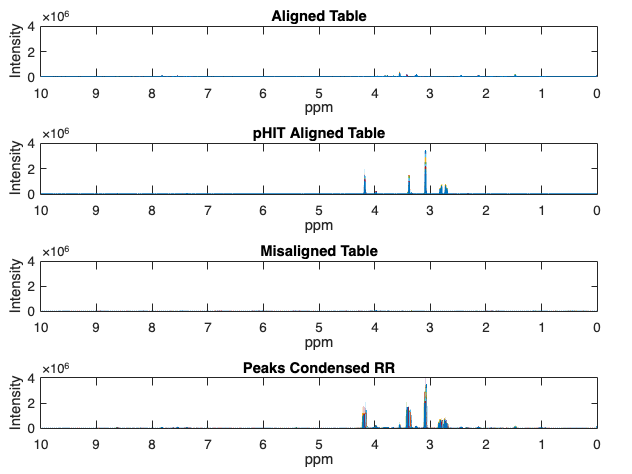


R_aligned    = syntheticUrine.Final.results.FieldResults.Aligned_Table  ;
R_misaligned = syntheticUrine.Final.results.FieldResults.Misaligned_Table;
R_condensed  = results.FieldResults.Con_RR_AF;
R_pHIT  = results.FieldResults.pHITRidgesAlign;



figure('Color','w');
t = tiledlayout(4,1,'TileSpacing','compact','Padding','compact');

ax = gobjects(4,1);   % store axes handles

%% ---  Aligned_Table ---
ax(1) = nexttile;
plot(R_aligned.reconstructed_ppm, R_aligned.X', 'LineWidth', 1.2);
set(gca,'XDir','reverse');
title('Aligned Table','Interpreter','none');
xlabel('ppm'); ylabel('Intensity');
xlim([0 10])   % zoom to 0–10 ppm

%% ---  pHIT Aligned ---
ax(2) = nexttile;
plot(R_pHIT.reconstructed_ppm, R_pHIT.X', 'LineWidth', 1.2);

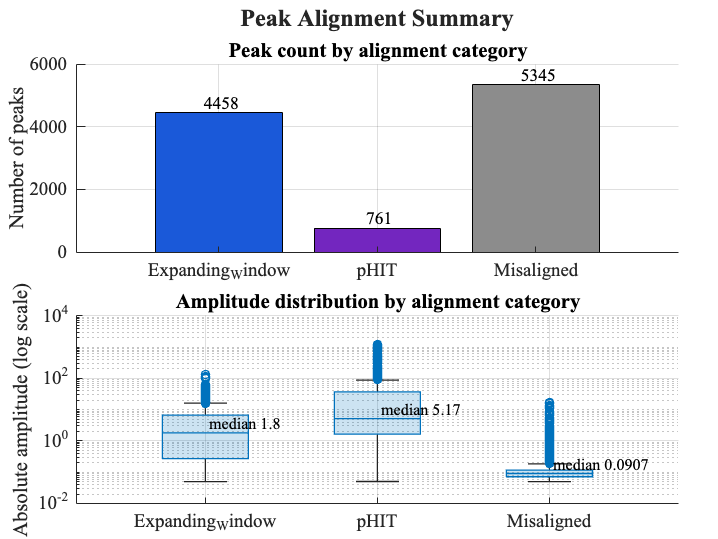

          Group           TotalPeaks    MeanAmplitude    MedianAmplitude    Q1Amplitude    Q3Amplitude    IQRAmplitude    MinAmplitude    MaxAmplitude    MeanCountPerSample    MedianCountPerSample
    __________________    __________    _____________    _______________    ___________    ___________    ____________    ____________    ____________    __________________    ____________________

    "Expanding_Window"       4458           6.7787            1.8011          0.27044         6.6384           6.368        0.050044         136.45             202.64                 203.5        
    "pHIT"                    761 

set(gca,'XDir','reverse');
title('pHIT Aligned Table','Interpreter','none');
xlabel('ppm'); ylabel('Intensity');
xlim([0 10])   % zoom to 0–10 ppm

%% --- Misaligned_Table ---
ax(3) = nexttile;
plot(R_misaligned.reconstructed_ppm, R_misaligned.X', 'LineWidth', 1.2);
set(gca,'XDir','reverse');
title('Misaligned Table','Interpreter','none');
xlabel('ppm'); ylabel('Intensity');
xlim([0 10])   % zoom to 0–10 ppm

%% --- Peaks_Condensed_RR ---
ax(4) = nexttile;
plot(R_condensed.reconstructed_ppm, R_condensed.X', 'LineWidth', 1.2);
set(gca,'XDir','reverse');
title('Peaks Condensed RR','Interpreter','none');
xlabel('ppm'); ylabel('Intensity');
xlim([0 10])   % zoom to 0–10 ppm



linkaxes(ax, 'xy');

**Plot 2: FR and peak SAND peak table**

figH = plotConsensusPHITValidation( ...
    results.FieldResults.All_Table, ...
    R_pHIT, ...
    syntheticUrine.alignedData, ...
    'AllTableName', 'All_Table', ...
    'PHITTableName', 'pHITRidgesAlign', ...
    'PPMColName', 'freq_ppm', ...
    'AlignedPPMCol', 'Aligned_PPM', ...
    'UseAlignedPPM', true, ...
    'InterFactor', 1);

**Plot 3: Summary statistics**

summaryStats = plotAlignmentPeakSummary(syntheticUrine.alignedData, ...
    'AlignedTableName', 'Aligned_Table', ...
    'MisalignedTableName', 'Misaligned_Table', ...
    'PHITTableName', 'pHITRidgesAlign', ...
    'AmplitudeCol', 'amplitude', ...
    ['UseAbsoluteA' ...
    'mplitude'], true, ...
    'MakeLogAmplitudePlot', true);